# 创建和训练深度学习模型

该脚本可创建和训练具有以下属性的深度学习网络:

运行此脚本以创建网络层、导入训练和验证数据并训练网络。网络层存储在工作区变量 `lgraph` 中。经过训练的网络存储在工作区变量 `net` 中。

要了解详细信息，请参阅 [从 Deep Network Designer 生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2020-07-13 09:01:31 自动生成

## 加载初始参数

加载用于网络初始化的参数。对于迁移学习，网络初始化参数是初始预训练网络的参数。

trainingSetup = load("D:\learn\TU Leben\4. Semester\arp\trainingSetup_2020_07_13__09_01_22.mat");

## 导入数据

导入训练和验证数据。

imdsTrain = imageDatastore("D:\learn\TU Leben\4. Semester\arp\img750","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsTest] = splitEachLabel(imdsTrain,0.9);
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

## 增强设置

imageAugmenter = imageDataAugmenter(...
    "RandRotation",[-90 90],...
    "RandYReflection",true);

% 调整图像大小以匹配网络输入层。
augimdsTrain = augmentedImageDatastore([227 227 3],imdsTrain,"DataAugmentation",imageAugmenter);
augimdsValidation = augmentedImageDatastore([227 227 3],imdsValidation);
augimdsTest = augmentedImageDatastore([227 227 3],imdsTest);

## 设置训练选项

指定训练时要使用的选项。

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## 创建层次图

创建层次图变量以包含网络层。

lgraph = layerGraph();

## 添加层分支

将网络分支添加到层次图中。每个分支均为一个线性层组。

tempLayers = [
    imageInputLayer([227 227 3],"Name","data","Mean",trainingSetup.data.Mean)
    convolution2dLayer([3 3],64,"Name","conv1","Stride",[2 2],"Bias",trainingSetup.conv1.Bias,"Weights",trainingSetup.conv1.Weights)
    reluLayer("Name","relu_conv1")
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    convolution2dLayer([1 1],16,"Name","fire2-squeeze1x1","Bias",trainingSetup.fire2_squeeze1x1.Bias,"Weights",trainingSetup.fire2_squeeze1x1.Weights)
    reluLayer("Name","fire2-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","fire2-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire2_expand3x3.Bias,"Weights",trainingSetup.fire2_expand3x3.Weights)
    reluLayer("Name","fire2-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","fire2-expand1x1","Bias",trainingSetup.fire2_expand1x1.Bias,"Weights",trainingSetup.fire2_expand1x1.Weights)
    reluLayer("Name","fire2-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire2-concat")
    convolution2dLayer([1 1],16,"Name","fire3-squeeze1x1","Bias",trainingSetup.fire3_squeeze1x1.Bias,"Weights",trainingSetup.fire3_squeeze1x1.Weights)
    reluLayer("Name","fire3-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","fire3-expand1x1","Bias",trainingSetup.fire3_expand1x1.Bias,"Weights",trainingSetup.fire3_expand1x1.Weights)
    reluLayer("Name","fire3-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","fire3-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire3_expand3x3.Bias,"Weights",trainingSetup.fire3_expand3x3.Weights)
    reluLayer("Name","fire3-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire3-concat")
    maxPooling2dLayer([3 3],"Name","pool3","Padding",[0 1 0 1],"Stride",[2 2])
    convolution2dLayer([1 1],32,"Name","fire4-squeeze1x1","Bias",trainingSetup.fire4_squeeze1x1.Bias,"Weights",trainingSetup.fire4_squeeze1x1.Weights)
    reluLayer("Name","fire4-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","fire4-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire4_expand3x3.Bias,"Weights",trainingSetup.fire4_expand3x3.Weights)
    reluLayer("Name","fire4-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","fire4-expand1x1","Bias",trainingSetup.fire4_expand1x1.Bias,"Weights",trainingSetup.fire4_expand1x1.Weights)
    reluLayer("Name","fire4-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire4-concat")
    convolution2dLayer([1 1],32,"Name","fire5-squeeze1x1","Bias",trainingSetup.fire5_squeeze1x1.Bias,"Weights",trainingSetup.fire5_squeeze1x1.Weights)
    reluLayer("Name","fire5-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","fire5-expand1x1","Bias",trainingSetup.fire5_expand1x1.Bias,"Weights",trainingSetup.fire5_expand1x1.Weights)
    reluLayer("Name","fire5-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","fire5-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire5_expand3x3.Bias,"Weights",trainingSetup.fire5_expand3x3.Weights)
    reluLayer("Name","fire5-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire5-concat")
    maxPooling2dLayer([3 3],"Name","pool5","Padding",[0 1 0 1],"Stride",[2 2])
    convolution2dLayer([1 1],48,"Name","fire6-squeeze1x1","Bias",trainingSetup.fire6_squeeze1x1.Bias,"Weights",trainingSetup.fire6_squeeze1x1.Weights)
    reluLayer("Name","fire6-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],192,"Name","fire6-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire6_expand3x3.Bias,"Weights",trainingSetup.fire6_expand3x3.Weights)
    reluLayer("Name","fire6-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","fire6-expand1x1","Bias",trainingSetup.fire6_expand1x1.Bias,"Weights",trainingSetup.fire6_expand1x1.Weights)
    reluLayer("Name","fire6-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire6-concat")
    convolution2dLayer([1 1],48,"Name","fire7-squeeze1x1","Bias",trainingSetup.fire7_squeeze1x1.Bias,"Weights",trainingSetup.fire7_squeeze1x1.Weights)
    reluLayer("Name","fire7-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],192,"Name","fire7-expand1x1","Bias",trainingSetup.fire7_expand1x1.Bias,"Weights",trainingSetup.fire7_expand1x1.Weights)
    reluLayer("Name","fire7-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],192,"Name","fire7-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire7_expand3x3.Bias,"Weights",trainingSetup.fire7_expand3x3.Weights)
    reluLayer("Name","fire7-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire7-concat")
    convolution2dLayer([1 1],64,"Name","fire8-squeeze1x1","Bias",trainingSetup.fire8_squeeze1x1.Bias,"Weights",trainingSetup.fire8_squeeze1x1.Weights)
    reluLayer("Name","fire8-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","fire8-expand1x1","Bias",trainingSetup.fire8_expand1x1.Bias,"Weights",trainingSetup.fire8_expand1x1.Weights)
    reluLayer("Name","fire8-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","fire8-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire8_expand3x3.Bias,"Weights",trainingSetup.fire8_expand3x3.Weights)
    reluLayer("Name","fire8-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire8-concat")
    convolution2dLayer([1 1],64,"Name","fire9-squeeze1x1","Bias",trainingSetup.fire9_squeeze1x1.Bias,"Weights",trainingSetup.fire9_squeeze1x1.Weights)
    reluLayer("Name","fire9-relu_squeeze1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","fire9-expand1x1","Bias",trainingSetup.fire9_expand1x1.Bias,"Weights",trainingSetup.fire9_expand1x1.Weights)
    reluLayer("Name","fire9-relu_expand1x1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],256,"Name","fire9-expand3x3","Padding",[1 1 1 1],"Bias",trainingSetup.fire9_expand3x3.Bias,"Weights",trainingSetup.fire9_expand3x3.Weights)
    reluLayer("Name","fire9-relu_expand3x3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","fire9-concat")
    dropoutLayer(0.5,"Name","drop9")
    convolution2dLayer([1 1],10,"Name","conv","BiasLearnRateFactor",0.1,"Padding","same")
    reluLayer("Name","relu_conv10")
    globalAveragePooling2dLayer("Name","pool10")
    softmaxLayer("Name","prob")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% 清理辅助函数变量
clear tempLayers;

## 连接层分支

连接网络的所有分支以创建网络图。

lgraph = connectLayers(lgraph,"fire2-relu_squeeze1x1","fire2-expand3x3");
lgraph = connectLayers(lgraph,"fire2-relu_squeeze1x1","fire2-expand1x1");
lgraph = connectLayers(lgraph,"fire2-relu_expand3x3","fire2-concat/in2");
lgraph = connectLayers(lgraph,"fire2-relu_expand1x1","fire2-concat/in1");
lgraph = connectLayers(lgraph,"fire3-relu_squeeze1x1","fire3-expand1x1");
lgraph = connectLayers(lgraph,"fire3-relu_squeeze1x1","fire3-expand3x3");
lgraph = connectLayers(lgraph,"fire3-relu_expand1x1","fire3-concat/in1");
lgraph = connectLayers(lgraph,"fire3-relu_expand3x3","fire3-concat/in2");
lgraph = connectLayers(lgraph,"fire4-relu_squeeze1x1","fire4-expand3x3");
lgraph = connectLayers(lgraph,"fire4-relu_squeeze1x1","fire4-expand1x1");
lgraph = connectLayers(lgraph,"fire4-relu_expand1x1","fire4-concat/in1");
lgraph = connectLayers(lgraph,"fire4-relu_expand3x3","fire4-concat/in2");
lgraph = connectLayers(lgraph,"fire5-relu_squeeze1x1","fire5-expand1x1");
lgraph = connectLayers(lgraph,"fire5-relu_squeeze1x1","fire5-expand3x3");
lgraph = connectLayers(lgraph,"fire5-relu_expand1x1","fire5-concat/in1");
lgraph = connectLayers(lgraph,"fire5-relu_expand3x3","fire5-concat/in2");
lgraph = connectLayers(lgraph,"fire6-relu_squeeze1x1","fire6-expand3x3");
lgraph = connectLayers(lgraph,"fire6-relu_squeeze1x1","fire6-expand1x1");
lgraph = connectLayers(lgraph,"fire6-relu_expand1x1","fire6-concat/in1");
lgraph = connectLayers(lgraph,"fire6-relu_expand3x3","fire6-concat/in2");
lgraph = connectLayers(lgraph,"fire7-relu_squeeze1x1","fire7-expand1x1");
lgraph = connectLayers(lgraph,"fire7-relu_squeeze1x1","fire7-expand3x3");
lgraph = connectLayers(lgraph,"fire7-relu_expand3x3","fire7-concat/in2");
lgraph = connectLayers(lgraph,"fire7-relu_expand1x1","fire7-concat/in1");
lgraph = connectLayers(lgraph,"fire8-relu_squeeze1x1","fire8-expand1x1");
lgraph = connectLayers(lgraph,"fire8-relu_squeeze1x1","fire8-expand3x3");
lgraph = connectLayers(lgraph,"fire8-relu_expand1x1","fire8-concat/in1");
lgraph = connectLayers(lgraph,"fire8-relu_expand3x3","fire8-concat/in2");
lgraph = connectLayers(lgraph,"fire9-relu_squeeze1x1","fire9-expand1x1");
lgraph = connectLayers(lgraph,"fire9-relu_squeeze1x1","fire9-expand3x3");
lgraph = connectLayers(lgraph,"fire9-relu_expand3x3","fire9-concat/in2");
lgraph = connectLayers(lgraph,"fire9-relu_expand1x1","fire9-concat/in1");

## 训练网络

使用指定的选项和训练数据对网络进行训练。

在单 GPU 上训练。
正在初始化输入数据归一化。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　１　｜　　　　１　｜　　　　　００：００：０４　｜　　　　４．６９％　｜　　１０．７５％　｜　　４．８３０４　｜　２．３７２７　｜　　０．０１００　｜


｜　　　３　｜　　　５０　｜　　　　　００：００：４１　｜　　　４７．６６％　｜　　４４．６３％　｜　　１．３７１２　｜　１．３４８１　｜　　０．０１００　｜


｜　　　５　｜　　１００　｜　　　　　００：０１：１８　｜　　　６４．８４％　｜　　７０．２２％　｜　　０．９９６０　｜　０．９３４５　｜　　０．０１００　｜


｜　　　７　｜　　１５０　｜　　　　　００：０１：５５　｜　　　２５．００％　｜　　２６．１７％　｜　　１．９５５６　｜　１．９９８１　｜　　０．０１００　｜


｜　　１０　｜　　２００　｜　　　　　００：０２：３６　｜　　　４７．６６％　｜　　４８．６５％　｜　　１．４２９８　｜　１．４２５８　｜　　０．０１００　｜


｜　　１２　｜　　２５０　｜　　　　　００：０３：１７　｜　　　６６．４１％　｜　　５２．９１％　｜　　１．１３２３　｜　１．２１５１　｜　　０．０１００　｜


｜　　１４　｜　　３００　｜　　　　　００：０４：０１　｜　　　７１．８８％　｜　　６４．８１％　｜　　０．７４４４　｜　０．８９２７　｜　　０．０１００　｜


｜　　１６　｜　　３５０　｜　　　　　００：０５：０３　｜　　　６７．９７％　｜　　６１．０３％　｜　　０．９５６９　｜　１．３０２３　｜　　０．０１００　｜


｜　　１９　｜　　４００　｜　　　　　００：０５：５５　｜　　　７９．６９％　｜　　７１．６２％　｜　　０．６０６８　｜　０．７３８０　｜　　０．０１００　｜


｜　　２１　｜　　４５０　｜　　　　　００：０６：５０　｜　　　８０．４７％　｜　　６８．９１％　｜　　０．６３９８　｜　０．８４９８　｜　　０．０１００　｜


｜　　２３　｜　　５００　｜　　　　　００：０７：４５　｜　　　７９．６９％　｜　　７６．５４％　｜　　０．５３７４　｜　０．６７２９　｜　　０．０１００　｜


｜　　２５　｜　　５５０　｜　　　　　００：０８：４５　｜　　　７８．９１％　｜　　７６．６２％　｜　　０．５８６４　｜　０．６４２５　｜　　０．０１００　｜


｜　　２８　｜　　６００　｜　　　　　００：０９：５６　｜　　　７７．３４％　｜　　７５．９６％　｜　　０．５９２０　｜　０．５８７８　｜　　０．０１００　｜


｜　　３０　｜　　６５０　｜　　　　　００：１１：０２　｜　　　８２．８１％　｜　　７６．６２％　｜　　０．５３２６　｜　０．５７７２　｜　　０．０１００　｜


｜　　３０　｜　　６６０　｜　　　　　００：１１：２２　｜　　　８０．４７％　｜　　７４．５７％　｜　　０．４８９２　｜　０．６７０９　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


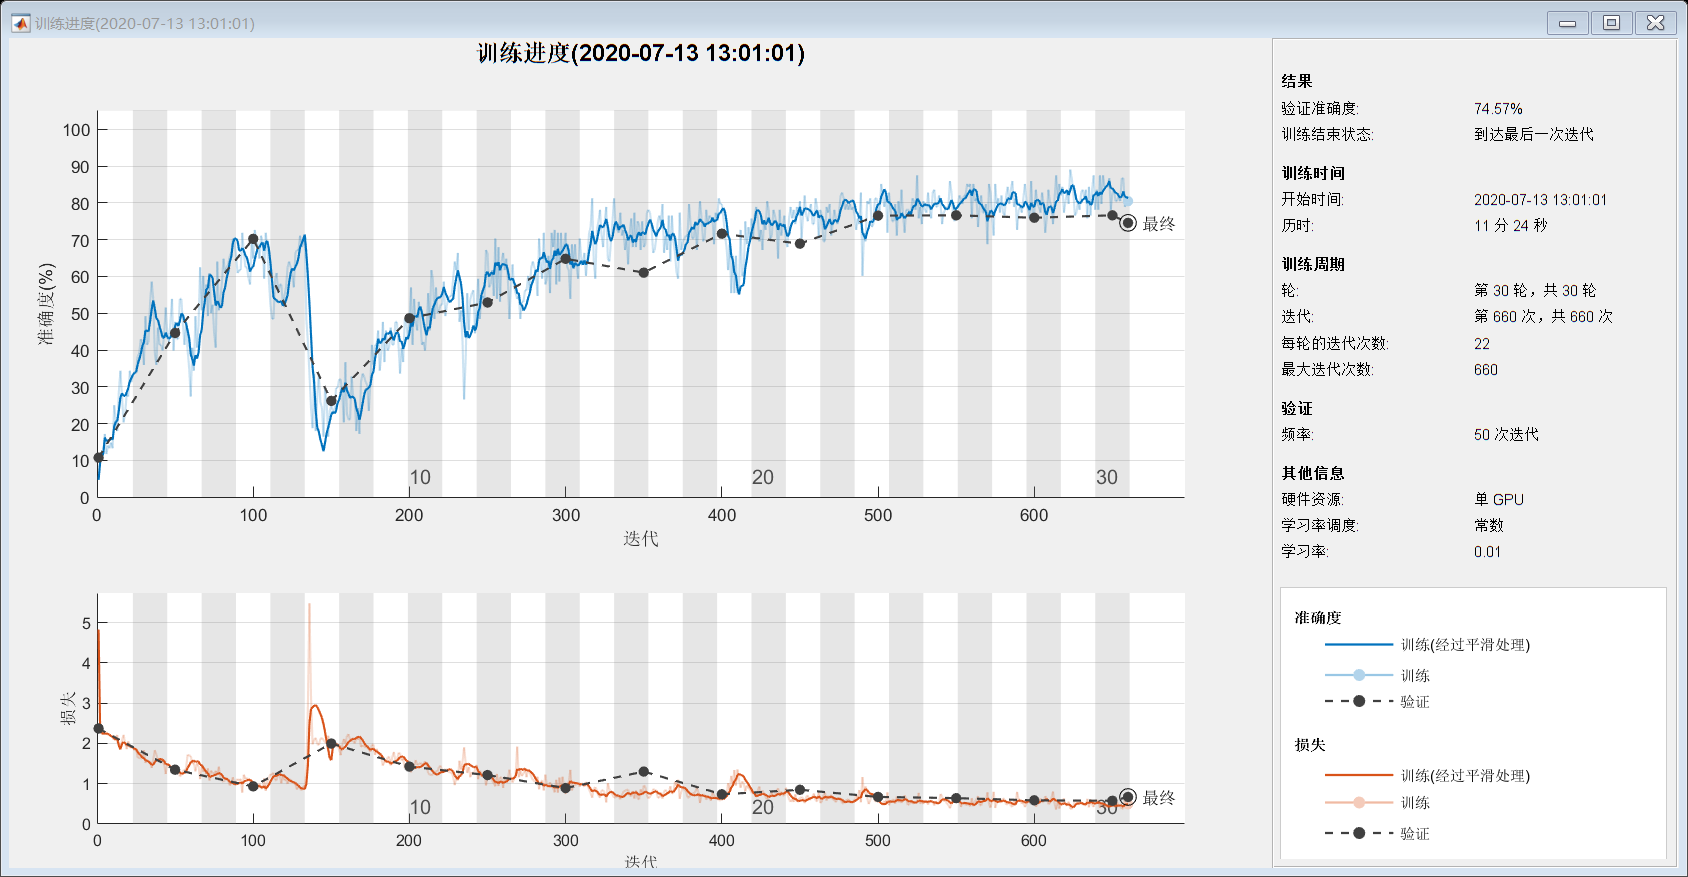

[net, traininfo] = trainNetwork(augimdsTrain,lgraph,opts);

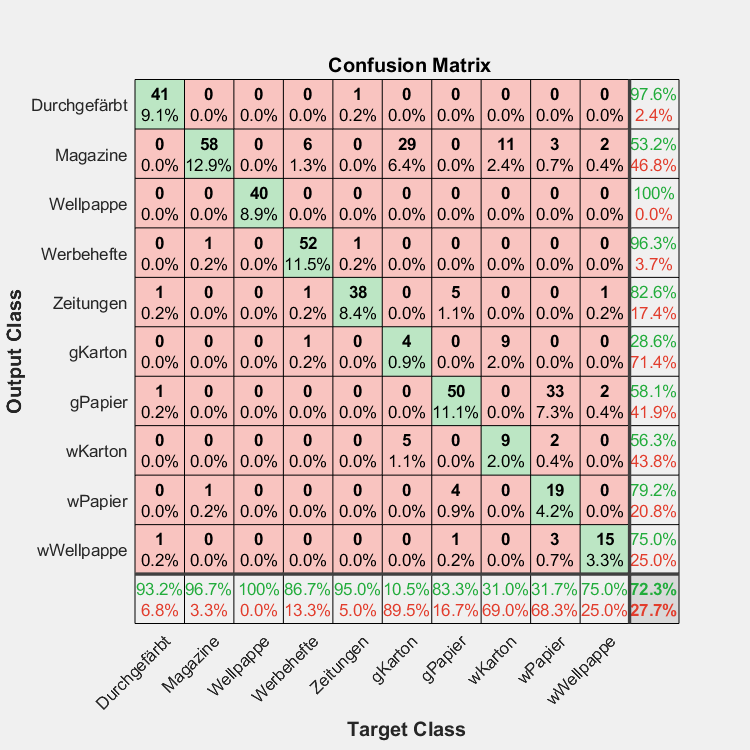

[YPred,scores] = classify(net,augimdsTest);
YTest = imdsTest.Labels;
accuracy = mean(YPred == YTest);
figure
plotconfusion(YTest,YPred);